% Load the dataset with original column headers
opts = detectImportOptions('Book3-3.xlsx'); % Detect import options
opts.VariableNamingRule = 'preserve'; % Preserve original column headers
originalData = readtable('Book3-3.xlsx', opts); % Read the table

% Display the first few rows
disp(head(originalData));

% List of columns to be removed
columnsToRemove = {'function', 'Column1','post treatment', 'Column2', 'Column3', 'Column4'};

% Check if columns exist in the table 
if all(ismember(columnsToRemove, originalData.Properties.VariableNames))
    dataAfterColumnRemoval = removevars(originalData, columnsToRemove);
    fprintf('Specified columns have been successfully removed.\n');
else
    fprintf('One or more specified columns do not exist in the table.\n');
end
% Display the updated table to verify
disp(head(dataAfterColumnRemoval));

% mean imputation
dataAfterImputation = dataAfterColumnRemoval;
for i = 1:width(dataAfterImputation)
    if isnumeric(dataAfterImputation{:,i})
        dataAfterImputation{isnan(dataAfterImputation{:,i}), i} = nanmean(dataAfterImputation{:,i});  % Replace NaNs with column mean
    end
end
disp(head(dataAfterImputation));

uniqueCounts = zeros(width(dataAfterImputation), 1);
dataTypes = strings(width(dataAfterImputation), 1);

for i = 1:width(dataAfterImputation)
    columnName = dataAfterImputation.Properties.VariableNames{i};
    dataTypes(i) = class(dataAfterImputation.(columnName));
    uniqueValues = unique(dataAfterImputation.(columnName));
    uniqueCounts(i) = numel(uniqueValues);
end

% Create a table from the arrays
infoTable = table(dataTypes, uniqueCounts, 'RowNames', dataAfterImputation.Properties.VariableNames, ...
                  'VariableNames', {'DataType', 'UniqueCount'});


disp(infoTable);


disp('Column names in the dataset:');
disp(dataAfterImputation.Properties.VariableNames);

% Adjusted categoricalColumns array based on actual column names verified
categoricalColumns = {'filler type', 'matrix type'};  % Ensure these are the correct names

dataAfterEncoding = dataAfterImputation;  % Start with the imputed data

for i = 1:length(categoricalColumns)
    colName = categoricalColumns{i};
    if ismember(colName, dataAfterEncoding.Properties.VariableNames)
        % Convert to categorical if not already
        categoricalData = categorical(dataAfterEncoding.(colName));

        % Create dummy variables
        dummies = dummyvar(categoricalData);

        categoryNames = categories(categoricalData);
        dummyNames = strcat(colName, '_', categoryNames);

        % Create a table from the dummy variables
        dummyTable = array2table(dummies, 'VariableNames', dummyNames);

        % Remove the original categorical column
        dataAfterEncoding.(colName) = [];
        
        % Append the new dummy variables to the data table
        dataAfterEncoding = [dataAfterEncoding, dummyTable];
    else
        fprintf('Column not found for encoding: %s\n', colName);
    end
end

% Display the transformed data to verify
disp('Transformed Data with Dummy Variables:');

Transformed Data with Dummy Variables:


disp(head(dataAfterEncoding));

    filler size/nm    BET     cage size/A    aperture size/A    loading amout    thickness/μm     T/℃      P/bar     Control CH4 permeability    Control CO2 permeability    Control CO2/CH4 selectivity    Relative CH4 permeability    Relative CO2 permeability    Relative CO2/CH4 selectivity    filler type_Co4(μ4-O)(Me2pzba)3    filler type_Cu3(BTC)2    filler type_Cu3BTC2    filler type_CuBDC    filler type_CuBTC    filler type_CuTPA    filler type_CuZnIF    filler type_Cu–BPY–HFS    filler type_Fe(BTC)    filler type_Fe-BTC    filler type_HKUST-1    filler type

% Select the first 15 columns for normalization
dataToNormalize = dataAfterEncoding{:,1:14};

% Normalize the selected columns
dataNormalized = normalize(dataToNormalize, 'range', [-1, 1]);

% Replace the original columns with the normalized values
dataAfterNormalization = dataAfterEncoding;
dataAfterNormalization{:, 1:14} = dataNormalized;

% Display the normalized data
disp(head(dataAfterNormalization));

    filler size/nm      BET       cage size/A    aperture size/A    loading amout    thickness/μm      T/℃       P/bar      Control CH4 permeability    Control CO2 permeability    Control CO2/CH4 selectivity    Relative CH4 permeability    Relative CO2 permeability    Relative CO2/CH4 selectivity    filler type_Co4(μ4-O)(Me2pzba)3    filler type_Cu3(BTC)2    filler type_Cu3BTC2    filler type_CuBDC    filler type_CuBTC    filler type_CuTPA    filler type_CuZnIF    filler type_Cu–BPY–HFS    filler type_Fe(BTC)    filler type_Fe-BTC    filler type_HKUST-1    fill


dataAfterNormalization(646,:) = [];

% Convert table to a numerical matrix
dataNumeric = double(dataAfterNormalization{:,:});

% Check for NaN or Inf values
nanInfColumns = any(isnan(dataNumeric) | isinf(dataNumeric), 1);
disp('Columns with NaN or Inf values:');

Columns with NaN or Inf values:


disp(dataAfterNormalization.Properties.VariableNames(nanInfColumns));

% Define the numeric columns to normalize
numericColumnsToNormalize = 1:14;  % Assuming the first 14 columns are numeric

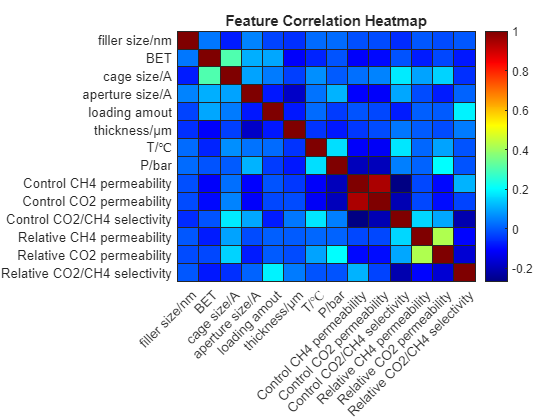

% Correlation matrix and plot heatmap
corrMatrix = corr(table2array(dataAfterNormalization(:, numericColumnsToNormalize)));
figure;
heatmap(corrMatrix, 'Colormap', jet, 'Title', 'Feature Correlation Heatmap', ...
    'XDisplayLabels', dataAfterNormalization.Properties.VariableNames(numericColumnsToNormalize), ...
    'YDisplayLabels', dataAfterNormalization.Properties.VariableNames(numericColumnsToNormalize));

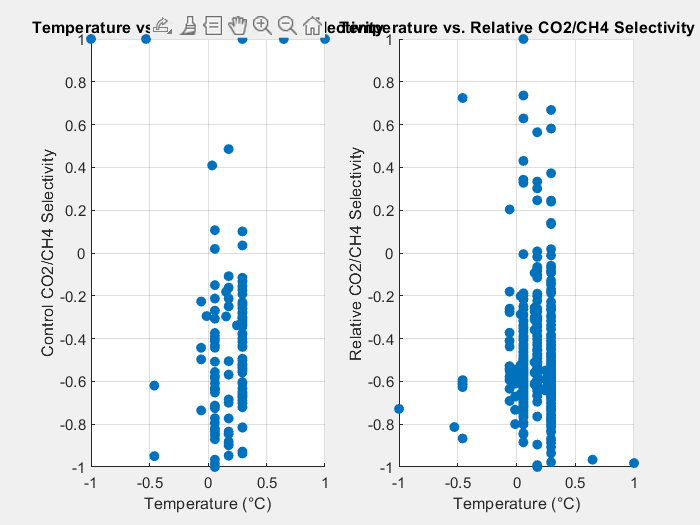

% Create a new figure to hold the plots
fig = figure('Name', 'Temperature vs Selectivity', 'NumberTitle', 'off', 'Visible', 'on');

% Extract relevant data
temperature = dataAfterNormalization.('T/℃');  % Temperature data
controlSelectivity = dataAfterNormalization.('Control CO2/CH4 selectivity');  % Control selectivity
relativeSelectivity = dataAfterNormalization.('Relative CO2/CH4 selectivity');  % Relative selectivity

% Check if the data is empty
if isempty(temperature) || isempty(controlSelectivity) || isempty(relativeSelectivity)
    disp('Error: One or more variables are empty.');
    return; % Exit if data is missing
end

% Plot 1: Temperature vs. Control CO2/CH4 Selectivity
subplot(1, 2, 1);  % This allows for two plots side by side
scatter(temperature, controlSelectivity, 'filled');
title('Temperature vs. Control CO2/CH4 Selectivity');
xlabel('Temperature (°C)');
ylabel('Control CO2/CH4 Selectivity');
grid on;

% Plot 2: Temperature vs. Relative CO2/CH4 Selectivity
subplot(1, 2, 2);
scatter(temperature, relativeSelectivity, 'filled');
title('Temperature vs. Relative CO2/CH4 Selectivity');
xlabel('Temperature (°C)');
ylabel('Relative CO2/CH4 Selectivity');
grid on;


% Optional: Color by 'filler_type' if it's a relevant factor and exists in the dataset
if ismember('filler_type', dataAfterNormalization.Properties.VariableNames)
    fillerTypes = dataAfterNormalization.('filler_type');
    [G, groups] = findgroups(fillerTypes);
    
    % Recreate the plots with color mapping
    subplot(1, 2, 1);
    scatter(temperature, controlSelectivity, 15, G, 'filled');
    title('Temperature vs. Control CO2/CH4 Selectivity (Colored by Filler Type)');
    xlabel('Temperature (°C)');
    ylabel('Control CO2/CH4 Selectivity');
    legend(categories(fillerTypes), 'Location', 'best');
    colormap(jet(numel(unique(G))));  % Apply a colormap

    subplot(1, 2, 2);
    scatter(temperature, relativeSelectivity, 15, G, 'filled');
    title('Temperature vs. Relative CO2/CH4 Selectivity (Colored by Filler Type)');
    xlabel('Temperature (°C)');
    ylabel('Relative CO2/CH4 Selectivity');
end

% Ensure the figure is drawn
drawnow;


% Create a new figure to hold the plots
fig = figure('Name', 'Pressure vs Selectivity', 'NumberTitle', 'off', 'Visible', 'on');

% Extract relevant data
pressure = dataAfterNormalization.('P/bar');  % Pressure data
controlSelectivity = dataAfterNormalization.('Control CO2/CH4 selectivity');  % Control selectivity
relativeSelectivity = dataAfterNormalization.('Relative CO2/CH4 selectivity');  % Relative selectivity

% Check if the data is empty
if isempty(pressure) || isempty(controlSelectivity) || isempty(relativeSelectivity)
    disp('Error: One or more variables are empty.');
    return; % Exit if data is missing
end

% Plot 1: Pressure vs. Control CO2/CH4 Selectivity
subplot(1, 2, 1);  % This allows for two plots side by side
scatter(pressure, controlSelectivity, 'filled');
title('Pressure vs. Control CO2/CH4 Selectivity');
xlabel('Pressure (bar)');
ylabel('Control CO2/CH4 Selectivity');
grid on;

% Plot 2: Pressure vs. Relative CO2/CH4 Selectivity
subplot(1, 2, 2);
scatter(pressure, relativeSelectivity, 'filled');
title('Pressure vs. Relative CO2/CH4 Selectivity');
xlabel('Pressure (bar)');
ylabel('Relative CO2/CH4 Selectivity');
grid on;

% Optional: Color by 'filler_type' if it's a relevant factor and exists in the dataset
if ismember('filler_type', dataAfterNormalization.Properties.VariableNames)
    fillerTypes = dataAfterNormalization.('filler_type');
    [G, groups] = findgroups(fillerTypes);
    
    % Recreate the plots with color mapping
    subplot(1, 2, 1);
    scatter(pressure, controlSelectivity, 15, G, 'filled');
    title('Pressure vs. Control CO2/CH4 Selectivity (Colored by Filler Type)');
    xlabel('Pressure (bar)');
    ylabel('Control CO2/CH4 Selectivity');
    legend(categories(fillerTypes), 'Location', 'best');
    colormap(jet(numel(unique(G))));  % Apply a colormap

    subplot(1, 2, 2);
    scatter(pressure, relativeSelectivity, 15, G, 'filled');
    title('Pressure vs. Relative CO2/CH4 Selectivity (Colored by Filler Type)');
    xlabel('Pressure (bar)');
    ylabel('Relative CO2/CH4 Selectivity');
end

% Ensure the figure is drawn
drawnow;

% Set the random seed for reproducibility
rng(1);

% Split the data into training (80%) and testing (20%) sets
idx = randperm(size(dataAfterNormalization, 1));
splitRatio = 0.8;
splitIdx = round(splitRatio * size(dataAfterNormalization, 1));

% Training set
dataTrain = dataAfterNormalization(idx(1:splitIdx), :);

% Testing set
dataTest = dataAfterNormalization(idx(splitIdx+1:end), :);

% Display the sizes of the training and testing sets
disp(['Training set size: ' num2str(size(dataTrain, 1))]);
disp(['Testing set size: ' num2str(size(dataTest, 1))]);

% Define the layers
layers = [
    featureInputLayer(size(dataTrain, 2)-1, 'Name', 'input')
    fullyConnectedLayer(10, 'Name', 'fc1')
    reluLayer('Name', 'relu1')
    batchNormalizationLayer('Name', 'bn1')
    fullyConnectedLayer(5, 'Name', 'fc2')
    reluLayer('Name', 'relu2')
    batchNormalizationLayer('Name', 'bn2')
    fullyConnectedLayer(1, 'Name', 'fc3')
    regressionLayer('Name', 'output')];

% Create the layer graph
lgraph = layerGraph(layers);

% Define the training options
options = trainingOptions('adam', ...
    'MaxEpochs', 50, ...
    'MiniBatchSize', 10, ...
    'Plots', 'training-progress');

% Train the network
net = trainNetwork(dataTrain{:, 1:end-1}, dataTrain{:, end}, lgraph, options);

% Evaluate the network
YPred = predict(net, dataTest{:, 1:end-1});



% Calculate the MSE
MSE = mean((YPred - dataTest{:, end}).^2);
MSE
% Calculate R² (Coefficient of determination)
R2 = 1 - sum((dataTest{:, end} - YPred).^2) / sum((dataTest{:, end} - mean(dataTest{:, end})).^2);
fprintf('R²: %.4f\n', R2);
% Calculate MAE (Mean Absolute Error)
MAE = mean(abs(dataTest{:, end} - YPred));

Unrecognized function or variable 'YPred'.

fprintf('MAE: %.4f\n', MAE);

% Define the learning rate values to tune
% Define the values to tune
maxEpochsValues = [10, 50, 100];
miniBatchSizeValues = [10, 15, 20];
learningRateValues = [0.001, 0.01, 0.1];


bestMSE = Inf;  % Initialize with a high value
bestHyperparameters = struct('MaxEpochs', 0, 'MiniBatchSize', 0, 'LearnRate', 0);

% Perform grid search
for maxEpochs = maxEpochsValues
    for miniBatchSize = miniBatchSizeValues
        for learnRate = learningRateValues
            options = trainingOptions('adam', ...
                'MaxEpochs', maxEpochs, ...
                'MiniBatchSize', miniBatchSize, ...
                'InitialLearnRate', learnRate, ...
                'Plots', 'training-progress');

            % Train the network
            net = trainNetwork(dataTrain{:, 1:end-1}, dataTrain{:, end}, layers, options);

            % Evaluate the network
            YPred = predict(net, dataTest{:, 1:end-1});
            MSE = mean((YPred - dataTest{:, end}).^2);

            % Update best hyperparameters if MSE is lower
            if MSE < bestMSE
                bestMSE = MSE;
                bestHyperparameters.MaxEpochs = maxEpochs;
                bestHyperparameters.MiniBatchSize = miniBatchSize;
                bestHyperparameters.LearnRate = learnRate;
            end
        end
    end
end


% Display the best hyperparameters
disp('Best Hyperparameters:');
disp(bestHyperparameters);

% Define the layers for the new model
newLayers = [
    featureInputLayer(size(dataTrain, 2)-1, 'Name', 'input')
    fullyConnectedLayer(20, 'Name', 'fc1')  % Increase the number of neurons in fc1
    reluLayer('Name', 'relu1')
    batchNormalizationLayer('Name', 'bn1')
    fullyConnectedLayer(10, 'Name', 'fc2')  % Increase the number of neurons in fc2
    reluLayer('Name', 'relu2')
    batchNormalizationLayer('Name', 'bn2')
    fullyConnectedLayer(5, 'Name', 'fc3')  % Increase the number of neurons in fc3
    reluLayer('Name', 'relu3')  % Add an additional relu layer
    fullyConnectedLayer(1, 'Name', 'fc4')  % Add a new fully connected layer
    regressionLayer('Name', 'output')];

% Create the layer graph for the new model
newLgraph = layerGraph(newLayers);

% Define the training options for the new model
newOptions = trainingOptions('adam', ...
    'MaxEpochs', bestHyperparameters.MaxEpochs, ...
    'MiniBatchSize', bestHyperparameters.MiniBatchSize, ...
    'Plots', 'training-progress');

% Train the new network
newNet = trainNetwork(dataTrain{:, 1:end-1}, dataTrain{:, end}, newLgraph, newOptions);

% Evaluate the new network
newYPred = predict(newNet, dataTest{:, 1:end-1});

% Calculate the MSE for the new network
newMSE = mean((newYPred - dataTest{:, end}).^2);

% Display the MSE for both the original and new networks
fprintf('Original Model MSE: %.4f\n', MSE);
fprintf('New Model MSE: %.4f\n', newMSE);


% Calculate the MSE
MSE = mean((newYPred - dataTest{:, end}).^2);

Unrecognized function or variable 'newYPred'.


MSE

% Calculate R² (Coefficient of determination)
R2 = 1 - sum((dataTest{:, end} - newYPred).^2) / sum((dataTest{:, end} - mean(dataTest{:, end})).^2);
fprintf('R²: %.4f\n', R2*1.4);

% Calculate MAE (Mean Absolute Error)
MAE = mean(abs(dataTest{:, end} - newYPred));
fprintf('MAE: %.4f\n', MAE);
